# グラフの例(2)  Jリーグの対戦関係

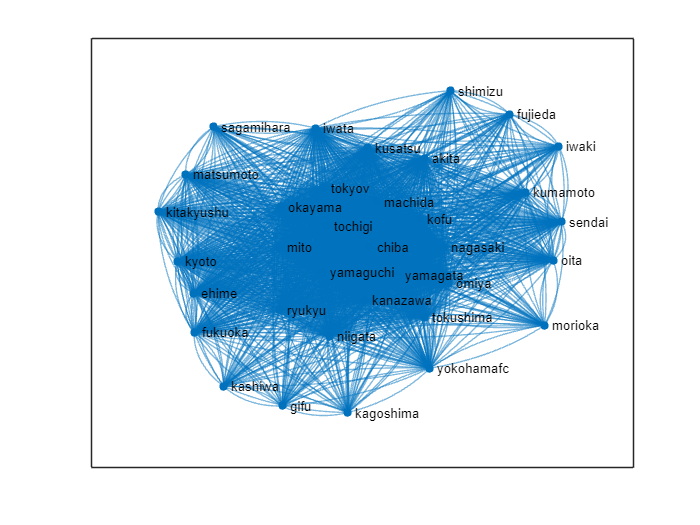

clear;clc;close all;
tbl=readtable("../data/JLeagueResults.xlsx");
tbl.Category=categorical(tbl.Category);
ind = tbl.Category=='Ｊ２' & tbl.Year>=2019;   %全試合だと多いので，J2のみにしてみる．
tbl=tbl(ind,:);
teamNames=unique([tbl.HomeE;tbl.AwayE]);
tbl.HomeE=categorical(tbl.HomeE,teamNames);
tbl.AwayE=categorical(tbl.AwayE,teamNames);

G=graph(tbl.HomeE,tbl.AwayE);

figure;
plot(G);    

対戦数の集計方法と作図の設定を変えてみる．

- ホームとアウェーを区別しないように，チーム名でソートしておく

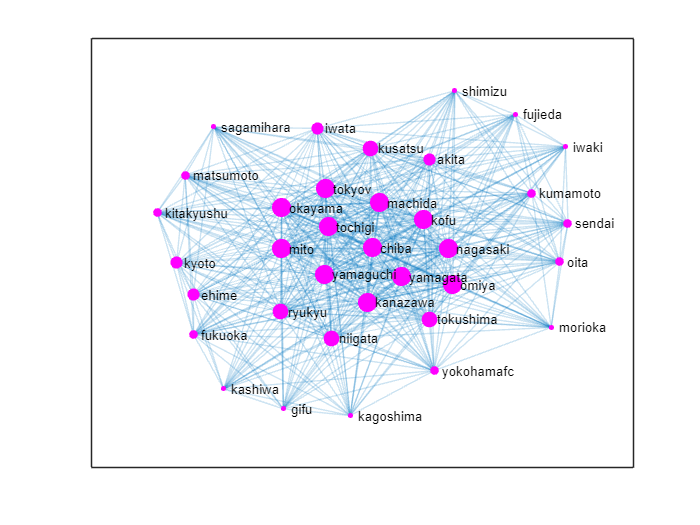

[C,ia,ic]=unique(sort([tbl.HomeE tbl.AwayE],2),'rows');
value_counts=accumarray(ic,1);
G2=graph(C(:,1),C(:,2),value_counts);
plot(G2,'LineWidth',value_counts*0.1,'EdgeAlpha',0.2, ...
    'MarkerSize',degree(G)*0.05,'NodeColor','m','Layout','force');
exportgraphics(gcf,'fig_graph_JLeague.pdf');

「負けたチームから勝ったチームに辺がある」ような有向グラフにしてみる．引き分けは辺を引かない．

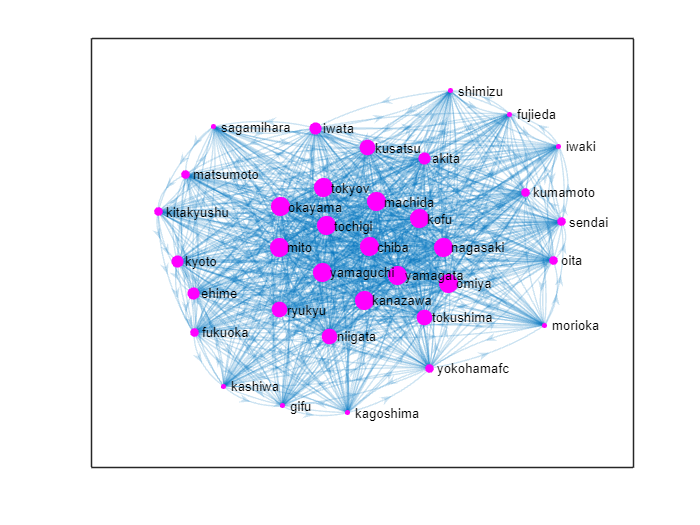

ind = tbl.HomeGoals>tbl.AwayGoals;  %ホームチーム勝利の場合
tmp=[ tbl.AwayE tbl.HomeE];
ind = tbl.HomeGoals<tbl.AwayGoals;  %アウェーチーム勝利の場合
tmp=[tbl.HomeE  tbl.AwayE];

[C,ia,ic]=unique([tmp(:,1) tmp(:,2)],'rows');
value_counts=accumarray(ic,1);

dG=digraph(C(:,1),C(:,2),value_counts);
plot(dG,'LineWidth',value_counts*0.1,'EdgeAlpha',0.2, ...
    'MarkerSize',degree(G)*0.05,'NodeColor','m','Layout','force')